Discussion HW3

**Introduction**

A skateboarder is moving along a curved path. The path is a section of circle of radius R = 10 m. The equation of motion is


$$\frac{d^2 \phi }{{\textrm{dt}}^2 }+\frac{g}{R}\sin \phi =0$$


where φ is an appropriately chosen angular coordinate. This equation has no closed form solution. It must be solved numerically. The initial conditions are  ̇φi = 0, and φi = either 10 or 70 deg (see below).

**Problems**

**(A)** (This part is not graded) Take some time to think about this problem and make these predictions first, based on whatever you know about physics and common sense; no detailed derivations required:

(1) Do you expect the skateboarder to oscillate back and forth with either set of initial conditions (yes, no)?

With phi equal to 0 we should see no oscillations as sin of phi would be 0. Any phi greater than 0 should cause oscillations.

(2) Do you expect that if the skateboarder starts at any initial φi they will oscillate back to that same amplitude after one period? (same, not same)?

It should be the same because there is no frictional or drag component affecting the motion.

(3) Do you expect the period of oscillation to be independent of the φi (period independent of φi, period dependent on φi)?

Yes

**(B)** Write down the Euler-Cromer finite difference solution to this ODE. Be sure to identify the general term a(t) (as presented in HW2) with its explicit expression in this case.


$$\begin{array}{l}
\frac{d^2 \phi }{{\mathrm{dt}}^2 }+\frac{g}{R}\sin \phi =0\\
\frac{d^2 \phi }{{\mathrm{dt}}^2 }=-\frac{g}{R}\sin \phi =a\\
\phi \left(t+\Delta t\right)=\phi \left(t\right)+\frac{1}{2}\left(\overset{\ldotp }{\phi} \left(t\right)+\left(\overset{\ldotp }{\phi} \left(t\right)-\omega^2 \phi \left(t\right)\Delta t\right)\right)
\end{array}$$


**(C)** In the Discussion we explained that ODE45 uses two 1st order ODEs to replace the single 2nd order ODE. Identify the equivalent of these two equations in the finite difference relations of part B.

The first first order ODE is,


$$\frac{d\phi }{\mathrm{dt}}=\overset{\ldotp }{\phi}$$


The second first ODE is,


$$\frac{d\overset{\ldotp }{\phi} }{\mathrm{dt}}=-\frac{g}{R}\sin \phi$$


**(D)** Write code to solve Equation 1 . You can use the code guidance posted on Canvas under Discussion 3. Use a total time span of 100 s. Plot the motion of the skateboarder, that is, φ(t) in degrees (not radians), over the first 30 s for each set of initial conditions.

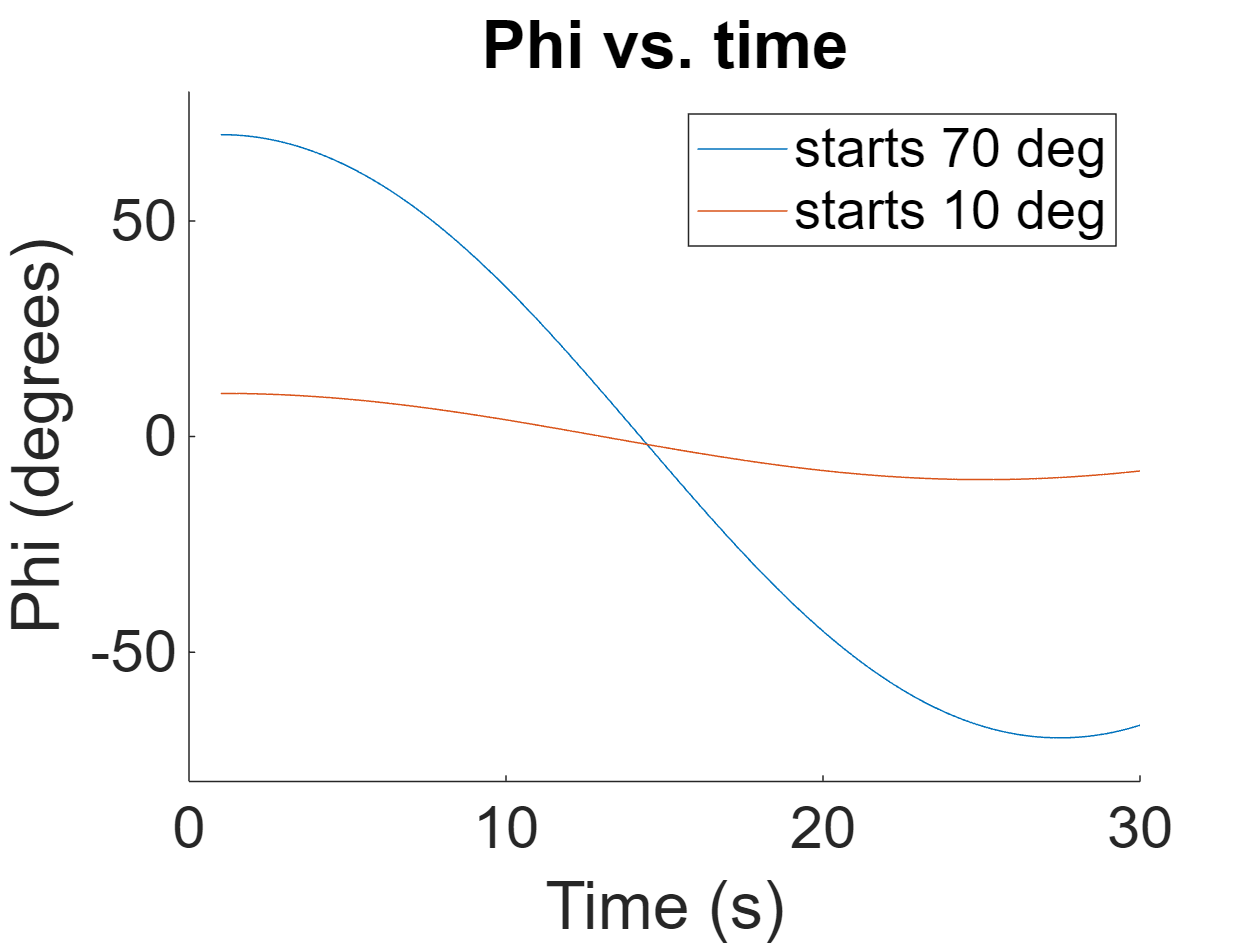

% Initial values
tspan = linspace(1, 100, 1000) ;
iphidot = 0 ; % initial value of phidot
% Declare ODE function seen above as a MatLab function
function phidot = odefun(t, phi)
    g = 9.8 ; % gravity (m/s^2)
    R = 10 ; % radius (m)
    % Set phidot as a state varible of phi (e.g phi(2) is phidot and so on)
    dphidt = phi(2) ;
    d2phidt2 = -(g / R)*sind(phi(1)) ;
    phidot = [dphidt; d2phidt2] ;
end
hold on
% Call ode45 with 10 degrees starting and 70 degrees starting
[t, phi_70] = ode45(@odefun, tspan, [70, iphidot]) ;
[t, phi_10] = ode45(@odefun, tspan, [10, iphidot]) ;
% Plot results
plot(t, phi_70(:, 1))
plot(t, phi_10(:, 1))
hold off
% Plot settings
title('Phi vs. time') ;
ylabel('Phi (degrees)') ;
xlabel('Time (s)') ;
set(gca, 'fontsize', 20)
xlim([0, 30]) ;
ylim([-80, 80]) ;
legend('starts 70 deg', 'starts 10 deg')

clf

**(E) **Now you must check that your solution makes sense. How do you propose to check your solution here. Please answer without going to the next page. You are not graded on this part, and there is no right or wrong answer.

I would check by treating the skateboarder as a (classic) simple harmonic oscillator and comparing the plots.

**(F)** One way to check your solution is to compare it to the solution of a classic harmonic oscillator (HO). Add to your livescript code that calculates φHO(t) for the classic harmonic oscillator that has the same parameters and the same two sets of initial conditions as used earlier. Overplot these results in the earlier Figures.


$$\begin{array}{l}
\left.\phi_{\mathrm{HO}} \left(t\right)=\phi_0 \sin \left(\omega t+\phi_0 \right)\approx \phi_0 \left(\omega t+\phi_0 \right)\right)\\
\omega =\sqrt{\frac{g}{r}}
\end{array}$$


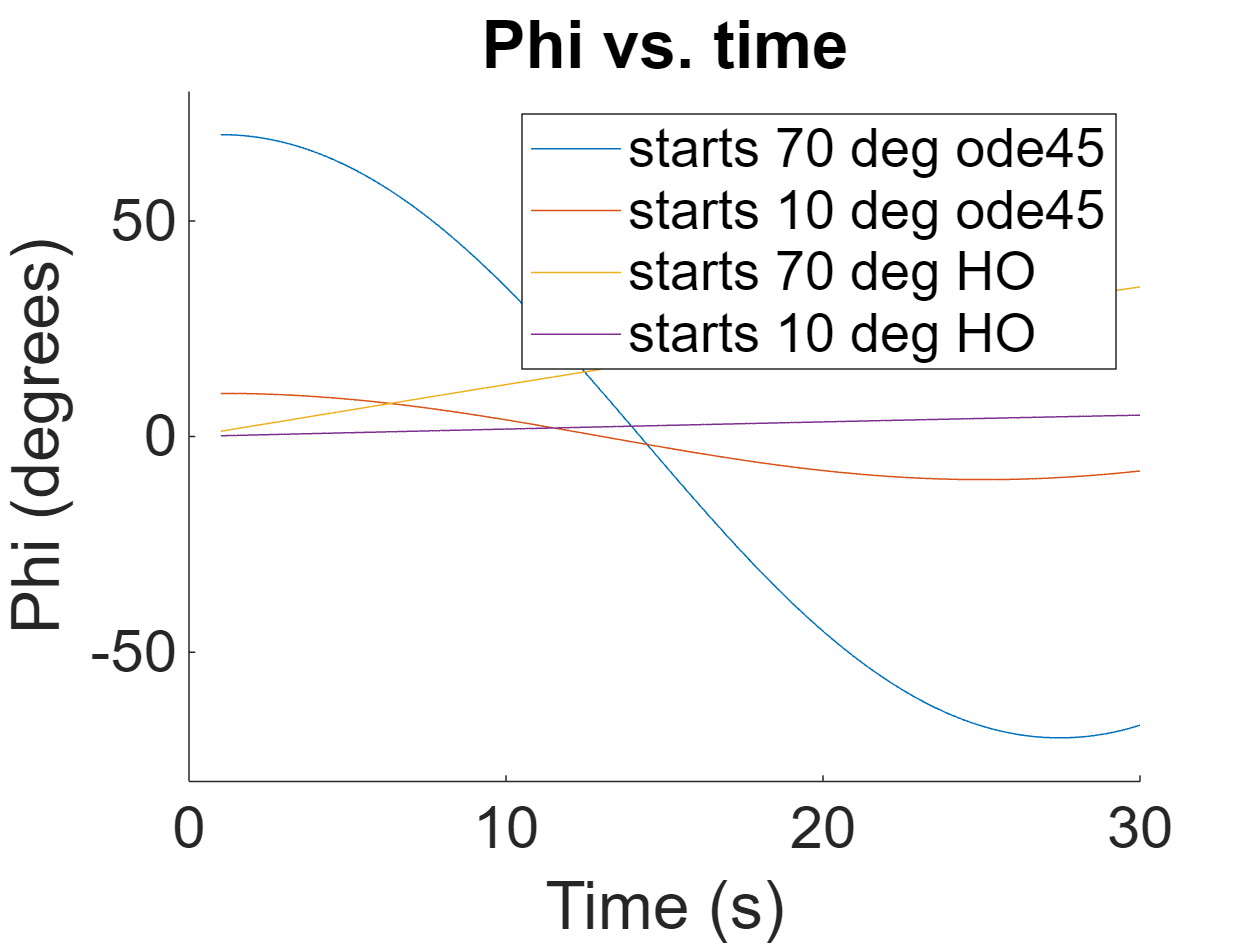

% Initial Varibles
g = 9.8 ; % gravity (m/s^2)
R = 10 ; % radius (m)
w = sqrt(g/R) ; % angular frequency (rad/s)
% Find phi using simple solution and the two initial values
phi_simple70 = 70*sind(w*tspan) ;
phi_simple10 = 10*sind(w*tspan) ;
% Plot results
hold on
plot(t, phi_70(:, 1))
plot(t, phi_10(:, 1))
plot(tspan , phi_simple70)
plot(tspan , phi_simple10)
hold off
% Plot settings
title('Phi vs. time') ;
ylabel('Phi (degrees)') ;
xlabel('Time (s)') ;
set(gca, 'fontsize', 20)
xlim([0, 30]) ;
ylim([-80, 80]) ;
legend('starts 70 deg ode45', 'starts 10 deg ode45', 'starts 70 deg HO', 'starts 10 deg HO', 'fontsize', 18)

clf

**(G)** Add a figure that gives the difference φ(t) − φHO(t).

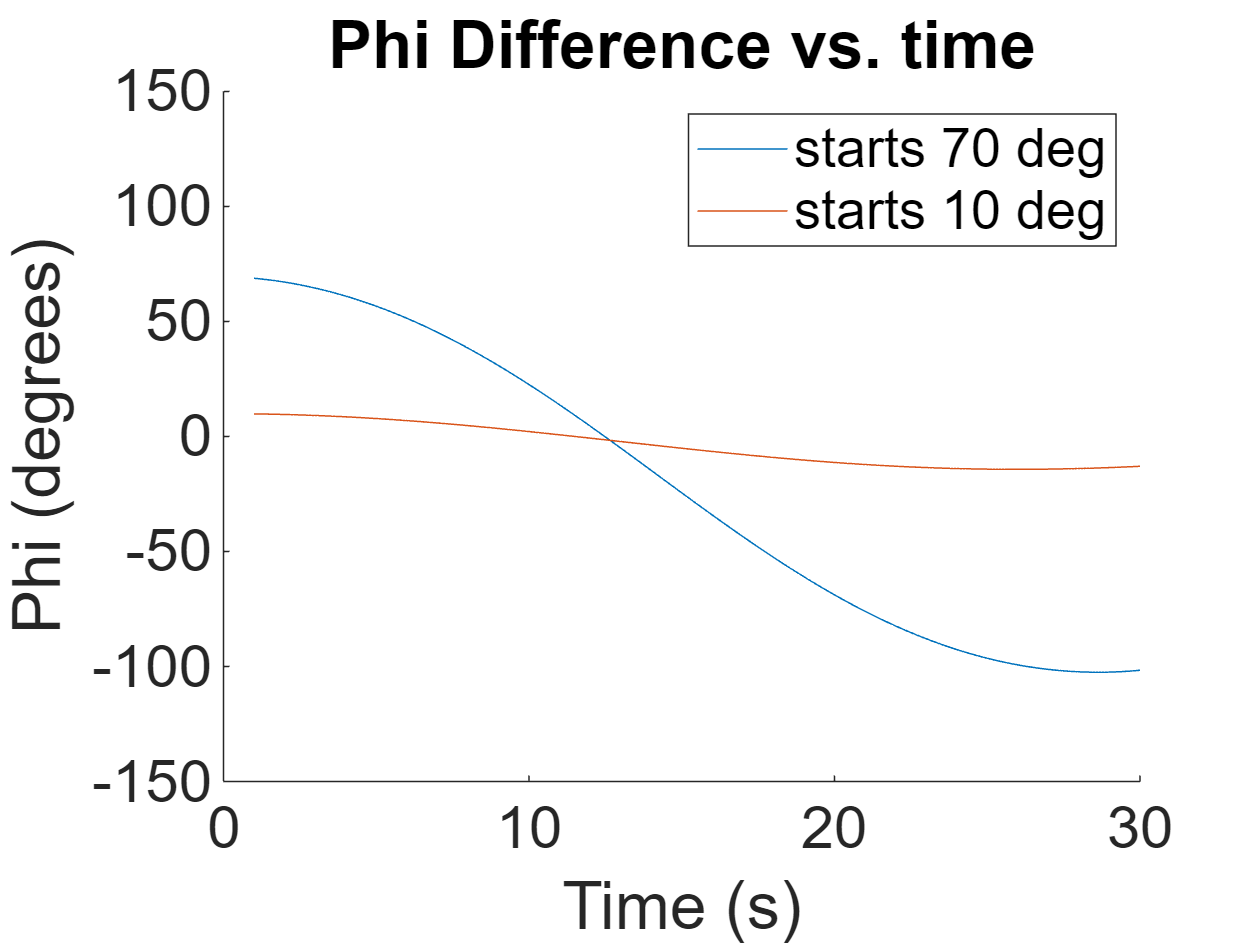

% Get Differences
diffphi70 = phi_70(:, 1)' - phi_simple70 ;
diffphi10 = phi_10(:, 1)' - phi_simple10 ;
% Plot
hold on
plot(tspan, diffphi70)
plot(tspan, diffphi10)
% Plot settings
title('Phi Difference (phi - phiHO) vs. time') ;
ylabel('Phi (degrees)') ;
xlabel('Time (s)') ;
set(gca, 'fontsize', 20)
xlim([0, 30]) ;
ylim([-150, 150]) ;
legend('starts 70 deg', 'starts 10 deg')

**(H)** Do the results make sense? Interpret the physics in words.

It makes sense as the difference is the sum of two sin waves with different starting points and create a new wave that is slightly shifted downwards meaning that phi_HO must be estimating over phi.

**(I)** Now revisit your predictions from part (A).

(1) Are the oscillations purely sinusoidal, that is, they are describable in terms of a sin

functions?

yes

(2) Is the amplitude conserved? If so, why?

yes, there are no drag forces of friction, just gravity.

(3) Physicists are told from young age that the period of oscillation of a pendulum are

independent of the amplitude of oscillations. That is, whether you set a pendulum at

5 degree or 15 degree initial offset, the period will be the same. (This is the basis of

the pendulum clock.) Is this true? Is the period with 20 degrees initial offset longer or

shorter than the period with 10 degrees initial offset

They look like they have the same inital offset meaning their period are the same and amplitude does not have an effect on the period.